% funkcija
f = @(x1, x2) 100 * (x2 - x1^2)^2 + (1 - x1)^2;

% Pocetne tocke
X1 = [-1; 1];
S1 = [4; 0];

f_alpha = @(alpha) f(X1(1) + alpha * S1(1), X1(2) + alpha * S1(2));

% testne tocke (podesivo)
alpha = [0, 0.001, 0.002, 0.0025];
phi = arrayfun(f_alpha, alpha);

% Maksimalno dvije refit
for refit = 1:2
    A = [alpha'.^3 alpha'.^2 alpha' ones(4,1)];
    koeficijenti = A \ phi';
% Kubna funkcija: phi(alpha) = a*alpha^3 + b*alpha^2 + c*alpha + d
    a = koeficijenti(1);
    b = koeficijenti(2);
    c = koeficijenti(3); 
    roots_poly = roots([3*a 2*b c]);
    alpha_new = NaN;
    for i = 1:length(roots_poly)
        if isreal(roots_poly(i)) && roots_poly(i) >= min(alpha) && roots_poly(i) <= max(alpha)
            alpha_new = roots_poly(i);
            break;
        end
    end
    phi_new = f_alpha(alpha_new);
    [~, idx_max] = max(phi);
    alpha(idx_max) = alpha_new;
    phi(idx_max) = phi_new;
end

% Najbolji rez
[~, idx_min] = min(phi);
alpha_min = alpha(idx_min);
X_min = X1 + alpha_min * S1;
f_min = f(X_min(1), X_min(2));

fprintf('Minimum funkcije ≈ %.6f\n', alpha_min);

Minimum alpha ≈ 0.001256


fprintf('X_min ≈ [%.6f, %.6f]\n', X_min(1), X_min(2));

X_min ≈ [-0.994975, 1.000000]


fprintf('f(X_min) ≈ %.6f\n', f_min);

f(X_min) ≈ 3.989975


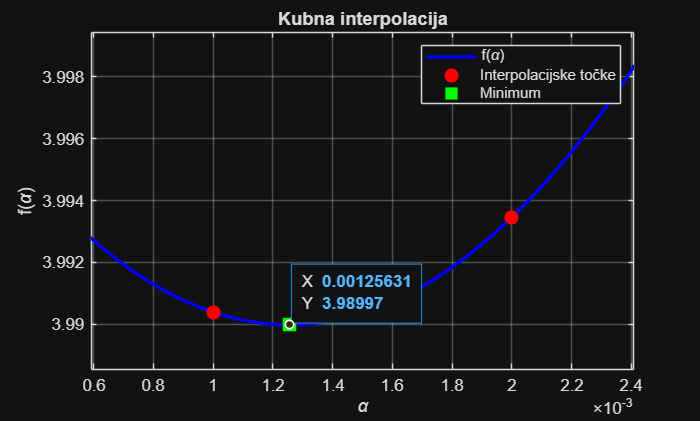


% plotanje

alpha_range = linspace(min(alpha)-0.0005, max(alpha)+0.0005, 500);
phi_range = arrayfun(f_alpha, alpha_range);

figure;
plot(alpha_range, phi_range, 'b-', 'LineWidth', 2); hold on;

plot(alpha, phi, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

% minimum
plot(alpha_min, f_min, 'gs', 'MarkerSize', 10, 'MarkerFaceColor', 'g');

xlabel('\alpha');
ylabel('f(\alpha)');
title('Kubna interpolacija');
legend('f(\alpha)', 'Interpolacijske točke', 'Minimum');
grid on;